# **Práctica 3: Diseño de Controladores PID**

Las prácticas de la asignatura Control con Computador consisten en el estudio de un servomecanismo de posicionamiento angular (LJ Technical Systems) controlado por un PC. Las sesiones de laboratorio P1 y P2 se centran en el análisis experimental de las respuestas temporal y frecuencial del sistema respectivamente. La sesión P3 se dedica al diseño de controladores PID.

**OBJETIVO: Diseñar un controlador PI de velocidad de salida para que el sistema de lazo cerrado tenga un error estacionario nulo. Diseñar un controlador PID de la posición del eje de salida para la planta estudiada en las sesiones anteriores para que el sistema en lazo cerrado cumpla unas ciertas especificaciones..**

**En esta sesión el estudiante ha de:**

- **Diseñar un PI y un PID por asignación de polos.**

- **Verificar experimentalmente el sistema de control diseñado.**

% Alternar entre los datos del experimento y los del directorio Resultados
% Si desea usar los datos del directorio Resultados = false
% Si desea usar datos propios = true
usarDatosExperimentales = false;

# Ejercicio 11: Diseño de un PI por asignación de polos.

# Ejercicio 12: Verificación experimental del sistema de control diseñado.

# Ejercicio 13: Diseño de un PID por asignación de polos.

Diseñar un PID de control de posición que haga que la respuesta temporal a una entrada escalón presente un sobreimpulso del 60% y una frecuencia de las oscilaciones de 0,7 Hz.

Para conseguirlo calcule el valor de los dos polos dominantes que cumplen con estas especificaciones y considere un tercer polo en 0,01. Toma el periodo de muestreo Ts igual a 0,01s. Determinar el valor de $k_p$,$\;k_i$ y $k_d$ y del 4º polo. Verificar si se cumple la hipótesis de polos dominantes. 

Abrir y ejecutar el modelo P3_Ex11.slx configurando una entrada escalon de 2V y un periodo de 10s. Comprobar si el sistema cumple las especificaciones mediante la simulación temporal del sistema ante un escalón. Repita la comprovación ensanchando los valores de la saturación en el bloque del controlador. Medir los valores de $S_p$, $t_p$, $\omega$ y $e_{\mathrm{ss}}$. 

Repita la medida del valor del error $e_{\textrm{ss}}$ cuando la entrada es una rampa. Repita el ejercicio pero ahora especificando un sobreimpulso del 80% y una frecuencia de oscilación de 1,0 Hz

# Ejercicio 13: Verificación experimental del sistema de control diseñado.

Abrir y ejecutar el modelo P3 Ex12.slx. Analizar el comportamiento del sistema de control experimental del laboratorio ante una entrada escalón de 2V y compruebar si se cumplen las especificaciones pedidas mediante la determinación de $S_p$, $t_p$, $\omega$ y $e_{\mathrm{ss}}$. Ante una entrada de rampa de 10s de periodo haga la comprovación con la medida del valor del error $e_{\textrm{ss}}$.

RESULTADO: No se parecen porque se fija un polo a mano y porque el sistema tiene 2 ceros que afectan a la dinamica del sistema.

# Ejercicio 15: Diseñar los mismos controladores pero con el bloque PID de Simulink.

Saber como se diseñan y diseñar controladore PID es muy importante, ya que seremos capaces de realizar un lazo de control donde se cumplan las especificaciones deseadas. Pero además de esto, tenemos que saber que MATLAB/Simulink ofrecen herramientas que simplifican nuestro trabajo. Por ejemplo, con la herramienta "*pidTuner*" podemos obtener las ganancias $k_p$,$\;k_i$ y $k_d$ teniendo solamente la función de transferencia de la planta y las especificaciones deseadas. Por otro lado, Simulink tiene un bloque especifico llamado "*PID Controller*" en el cual podemos especificar las ganancias de cada acción, coeficiente del filtro de la parte derivativa... 

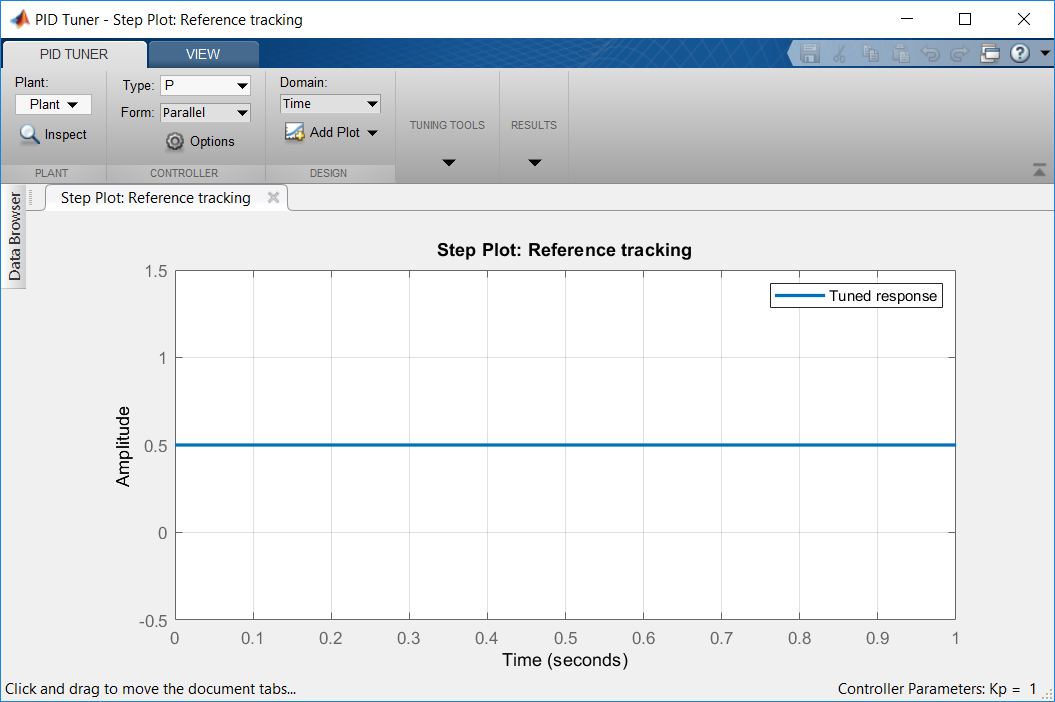

Figure 1: Herramienta pidTuner

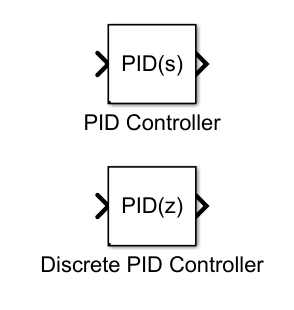

Figure 2: Bloques PID de Simulink

En este ejercicio se desea implementar el mismo controlador pero usando este bloque especifico. Para ello, abrir y ejecutar el modelo P3 Ex13.slx y comprobar que los resultados obtenidos en este ejercicio se asemeja a los resultados obtenidos en el ejercicio 12.